# **Numerical Integration **

**Numerical Programming**

## Part 1.  Integration from Datasets

Here, we DO NOT  assume evenly distributed data

## Example Problem

Estimate the velocity from the dataset of acceleration 

clear all

x=[0 5 10 15 20 25 30 35 40 45 50 55 60];
y=[0 3 8 20 33 42 40 48 60 12 8 4 3];
N=length(x)

N =     13


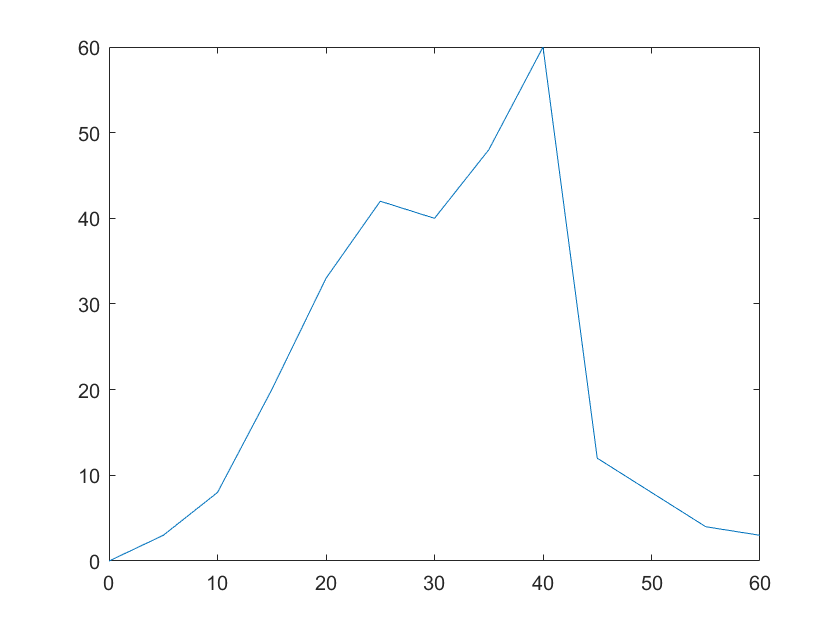

plot (x,y)

### Matlab function for Discrete data:  I_matlab = trapz(x,y);    

formatSpec = 'I= %3.6f  with Error %2.3f%% \n';

% Matlab function
I_matlab = trapz(x,y);    

I_true=I_matlab;
fprintf(formatSpec,I_matlab,0)

I= 1397.500000  with Error 0.000% 


### Rectangle Method:

% Rectangle Method
Ir=0;
for k=1:N-1
    Ir= Ir+y(k)*(x(k+1)-x(k));
end

error_Ir=abs((Ir-I_true)/I_true)*100;
fprintf(formatSpec,Ir,error_Ir)

I= 1390.000000  with Error 0.537% 


###  Trapezoidal Method

It=0;
for k=1:N-1
    It=It+ 0.5* (y(k)+y(k+1))*(x(k+1)-x(k));
end

error_It=abs((It-I_true)/I_true)*100;
fprintf(formatSpec,It,error_It)

I= 1397.500000  with Error 0.000% 


## Part 2.  Integration from a Function

Here, we  assume evenly distributed data

## Example Problem

The area of the shaded region shown in the figure can be calculated by:

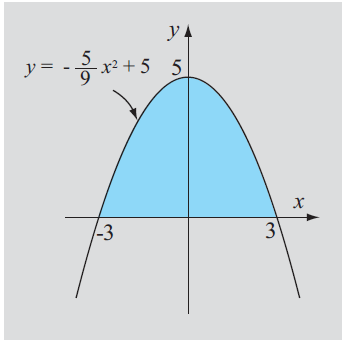

%% Example 1
clear, clc
format long
a=-3; b=3;
N=8;
h=(b-a)/N;
x=a:h:b;

fun=@(x) -(5/9)*x.^2+5;
I_true=20;

Example 2:  Area of Unit Semi-Circle

a=-1; b=1;
N=8;
h=(b-a)/N;
fun=@(x) (1-x.^2).^0.5;
I_true=pi/2;

Evaluate and compare the numerical integral using the several methods: when N=4, N=8

formatSpec = 'I= %3.6f  with Error %2.3f%% \n';

% Matlab function
I_matlab = quad(fun,a,b);    
error_matlab=abs((I_matlab-I_true)/I_true)*100;
fprintf(formatSpec,I_matlab,error_matlab)

I= 1.570789  with Error 0.000% 



% Rectangle Method
Ir = IntegrateRectangle(fun,a,b,N);
error_Ir=abs((Ir-I_true)/I_true)*100;
fprintf(formatSpec,Ir,error_Ir)

I= 1.497855  with Error 4.644% 



% Trapezoidal Method
It=trapezoidal(fun,a,b,N);
error_It=abs((It-I_true)/I_true)*100;
fprintf(formatSpec,It,error_It)

I= 1.497855  with Error 4.644% 



% Simpson 1/3 Method
Is=Simpson(fun,a,b,N);
error_Is=abs((Is-I_true)/I_true)*100;
fprintf(formatSpec,Is,error_Is)

I= 1.541798  with Error 1.846% 



% Adaptive Simpson Method
Ia = AdaptSimpson(fun,a,b);             

 Max.Itr reached
 Max.Itr reached
 Max.Itr reached
 Max.Itr reached


error_Ia=abs((Ia-I_true)/I_true)*100;
fprintf(formatSpec,Ia,error_Ia)

I= 1.570776  with Error 0.001% 
